%{
    This script calculates correlations of the raw original signals.
%}

warning('off','all')

rawDataArray = {numOfFiles};
for fileIndex = 1 : numOfFiles
    % Load the data for the current file
    rawDataStruct = load(dataSubfolder + filenames(fileIndex) + ".mat");
    rawDataArray{fileIndex} = struct2array(rawDataStruct); 
end

r2Val = zeros(numOfSignals, numOfSignals);
r2Values = zeros(numOfFiles, numOfSignals, numOfSignals);
for fileIndex = 1 : numOfFiles
%    fprintf("File #%i", fileIndex);
    for sensorIndex1 = 1 : numOfSignals
        for sensorIndex2 = sensorIndex1 : numOfSignals
            sig1 = rawDataArray{fileIndex}{sensorIndex1,2};
            sig2 = rawDataArray{fileIndex}{sensorIndex2,2};
            mdl = fitlm(sig1, sig2);
            R2 = mdl.Rsquared.Ordinary;
%             if R2 > 0.2 && R2 < 0.8
%                 figure(); hold on; plot(sig1); yyaxis right; plot(sig2); 
%                 title(sensorNames(sensorIndex1) + " & " + sensorNames(sensorIndex2));
%                 figure(); scatter(sig1, sig2, "filled");
%                 title(sensorNames(sensorIndex1) + " vs " + sensorNames(sensorIndex2));
%             end
%            fprintf("File %i: Signal %i / Signal %i, R2 = %.3g \n", fileIndex,sensorIndex1, sensorIndex2, R2)
            r2Val(sensorIndex1, sensorIndex2) = R2;
            r2Values(fileIndex, sensorIndex1, sensorIndex2) = R2;
        end
    end
end

addpath('C:\Users\PaulBarron\Dropbox\Thesis\matrix2latex')
M = r2Values(1, :, 1)';
for i = 2:size(r2Values,3)
    M = [ M r2Values(1,:, i)' ];
end

rowLabels = { '07', '10', '12', '17', '20', '28', '31', '32', '33', '34', '35', '36' };
columnLabels = rowLabels;

matrix2latex(M, '..\Latex Document\tables\correlationTable.tex', 'rowLabels', rowLabels, 'columnLabels', columnLabels, 'alignment', 'c', 'format', '%-6.2f', 'size', 'tiny');

## Plot table for the correlation of each raw signal in a particular file

arr = [1:1:12];
labels = arrayfun(@num2str, arr, 'UniformOutput', 0);
array2table(r2Val, 'VariableNames',	labels);

## Plot table for the correlation of each raw signal in a particular file

for fileIndex = 1:numOfFiles
    arr = [1:1:12];
    labels = arrayfun(@num2str, arr, 'UniformOutput', 0);
    fprintf("Filenumber #%i", fileIndex)
    arrTable = array2table(squeeze(r2Values(fileIndex, :, :)), 'VariableNames',	labels)
end

Filenumber #1

arrTable = 12×12 table
    1       2          3           4           5           6           7            8            9           10        11         12     
    _    _______    ________    ________    ________    ________    ________    _________    _________    ________    ____    ___________

    1    0.92861    0.072707      0.3675    0.065114    0.051261     0.21795      0.20367      0.20573     0.21796    -Inf        0.16393
    0          1    0.070488     0.44055    0.063314    0.072418     0.26168      0.24579      0.24807      0.2617    -Inf        0.19686
    0          0

Filenumber #2

arrTable = 12×12 table
    1       2          3          4           5           6            7             8             9            10         11         12     
    _    _______    _______    ________    ________    ________    __________    __________    _________    __________    ____    ___________

    1    0.29732    0.14225    0.058199     0.13897     0.10511    6.3074e-06       0.10091     0.057402    0.00054671    -Inf      0.0095892
    0          1    0.07749    0.001715    0.074941    0.046959     0.0075049      0.090003    0.0015018    0.00050541    -Inf        0.11298


Filenumber #3

arrTable = 12×12 table
    1       2           3             4            5             6            7           8            9             10         11         12    
    _    _______    __________    _________    __________    _________    _________    ________    __________    __________    ____    __________

    1    0.11609      0.077339    0.0021121       0.06993     0.013875        0.163     0.13748     0.0018398     0.0096207    -Inf      0.045023
    0          1    0.00045767    0.0043065    0.00037914    0.0032602      0.78333     0.29805       0.35867      0.074298    -In

Filenumber #4

arrTable = 12×12 table
    1       2            3             4             5             6             7            8             9            10         11         12     
    _    ________    __________    __________    __________    __________    _________    __________    __________    _________    ____    ___________

    1    0.066675    2.1472e-05      0.010025    0.00013623       0.01963     0.038803        0.4545       0.45591     0.026689    -Inf      0.0038445
    0           1      0.022975    9.3809e-05      0.020446    0.00027632      0.23248       0.14808       0.14177 

Filenumber #5

arrTable = 12×12 table
    1       2           3             4            5            6           7           8            9             10         11         12     
    _    _______    __________    _________    _________    _________    ________    ________    __________    __________    ____    ___________

    1    0.75956    0.00093403      0.27822    0.0020498    0.0017373      0.1786     0.26871     0.0003167       0.47184    -Inf       0.044473
    0          1     0.0093203      0.25463    0.0063633     0.013322     0.23056     0.34554    0.00040554       0.60517    -Inf    

Filenumber #6

arrTable = 12×12 table
       1          2           3          4          5           6             7              8              9             10         11         12    
    _______    ________    _______    _______    _______    __________    __________    ___________    ___________    __________    ____    __________

    0.46022    -0.31574     -2.492    -1.8156     -2.492    7.9936e-15    6.5503e-15    -1.3767e-14    -2.6645e-15    7.5495e-15    -Inf    1.3323e-15
          0    -0.99308    -2.3426    -1.6475    -2.3426    1.0325e-14      1.41e-14    -4.4409e-16    -2.8866e-15 

Filenumber #7

arrTable = 12×12 table
    1       2            3            4            5            6             7            8             9             10           11            12    
    _    ________    _________    _________    _________    __________    _________    __________    __________    __________    _________    __________

    1    0.054205    0.0028762      0.96569    0.0031986    0.00064486       0.7006       0.62882      0.037237     0.0013322        0.615      0.040532
    0           1     0.012766     0.025016     0.011851     0.0012528     0.049595      0.040115    0.000787

Filenumber #8

arrTable = 12×12 table
    1       2          3          4          5          6          7          8           9             10         11         12     
    _    _______    _______    _______    _______    _______    _______    _______    __________    __________    ____    ___________

    1    0.56081     0.2965    0.96089    0.26266    0.10073    0.86871     0.8844     2.712e-07      0.023539    -Inf        0.10469
    0          1    0.35655    0.70595    0.31295    0.14702    0.83043    0.81668     0.0018818      0.019389    -Inf       0.098716
    0          0          1    0

Filenumber #9

arrTable = 12×12 table
    1       2           3           4           5            6             7             8           9           10          11            12    
    _    _______    _________    _______    _________    __________    __________    _________    ________    ________    _________    __________

    1    0.39589      0.24849    0.99824      0.21203      0.068315       0.24161     0.066263    0.010467    0.054453      0.39886      0.015498
    0          1    0.0047139    0.39198    0.0032011    1.2352e-06       0.42593    0.0018499    0.011777     0.13009      0.2730

Filenumber #10

arrTable = 12×12 table
    1       2          3          4          5           6           7           8           9          10          11          12   
    _    _______    _______    _______    _______    _________    ________    ________    _______    ________    ________    ________

    1    0.91819    0.44892    0.98375    0.36311    0.0090659     0.89232     0.81397    0.68083     0.88802     0.76025     0.34929
    0          1    0.60913    0.85927    0.52577     0.053112     0.96292     0.85726    0.71787     0.96057     0.81816      0.3766
    0          0          1    0

Filenumber #11

arrTable = 12×12 table
    1       2          3          4          5          6            7             8             9             10         11         12     
    _    _______    _______    _______    _______    ________    __________    __________    __________    __________    ____    ___________

    1    0.77717    0.34945    0.99532    0.30513    0.094727      0.035598     0.0011237      0.012568       0.04119    -Inf       0.087751
    0          1     0.1995    0.78872    0.16174    0.022503    0.00088163      0.010588     0.0058658    0.00088141    -Inf        0.08139
    

Filenumber #12

arrTable = 12×12 table
    1       2          3          4          5          6           7             8            9            10         11         12     
    _    _______    _______    _______    _______    _______    __________    _________    _________    __________    ____    ___________

    1    0.93872    0.42715     0.9631    0.37383    0.19124     0.0008217      0.12403      0.12506    0.00081951    -Inf       0.061073
    0          1    0.33841    0.84243    0.30213    0.18196       0.00943      0.11332        0.114     0.0094174    -Inf       0.044704
    0          0

Filenumber #13

arrTable = 12×12 table
    1       2           3           4           5           6           7           8            9            10        11         12    
    _    ________    ________    ________    ________    ________    ________    ________    __________    ________    ____    __________

    1    0.037184     0.54099    0.050071     0.49381     0.31584         0.9     0.89593      0.027724     0.48531    -Inf      0.065919
    0           1    0.029656     0.84052    0.027188    0.010474    0.040667     0.03934     0.0032076    0.023271    -Inf      0.038848
    0           

Filenumber #14

arrTable = 12×12 table
    1       2           3            4            5           6           7           8           9          10        11         12     
    _    _______    _________    _________    _________    ________    ________    ________    ________    _______    ____    ___________

    1    0.57323    0.0099997    0.0030021    0.0096472    0.006678     0.24496     0.04193    0.042883    0.24507    -Inf      0.0087646
    0          1      0.15453    0.0060064      0.14841    0.079628     0.30568     0.11044     0.11167    0.30579    -Inf        0.02169
    0          0

Filenumber #15

arrTable = 12×12 table
    1        2            3            4            5            6             7            8            9            10         11         12    
    _    _________    _________    _________    _________    __________    _________    _________    __________    _________    ____    __________

    1    0.0001021     0.038185      0.66748      0.04093      0.023008      0.41284      0.31809       0.37859     0.036162    -Inf      0.025013
    0            1    0.0080902    0.0001223    0.0060038    7.7611e-05      0.00037    0.0072128     0.0069968       0.0454   

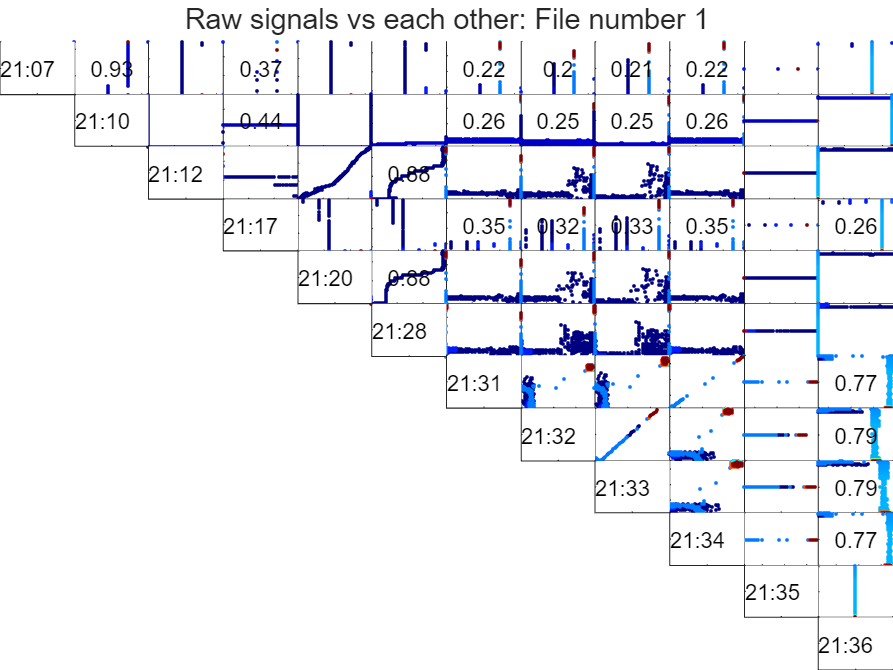

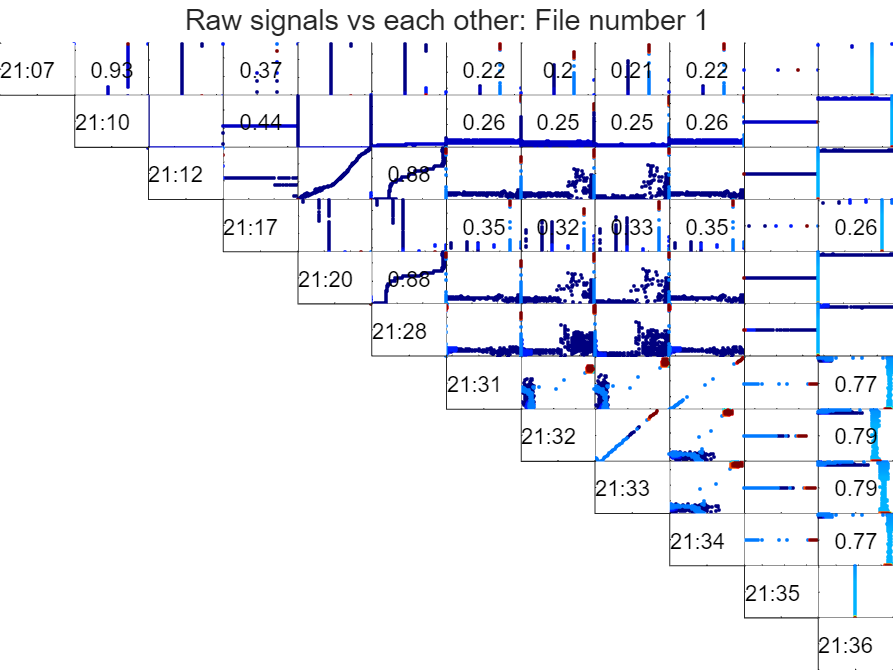

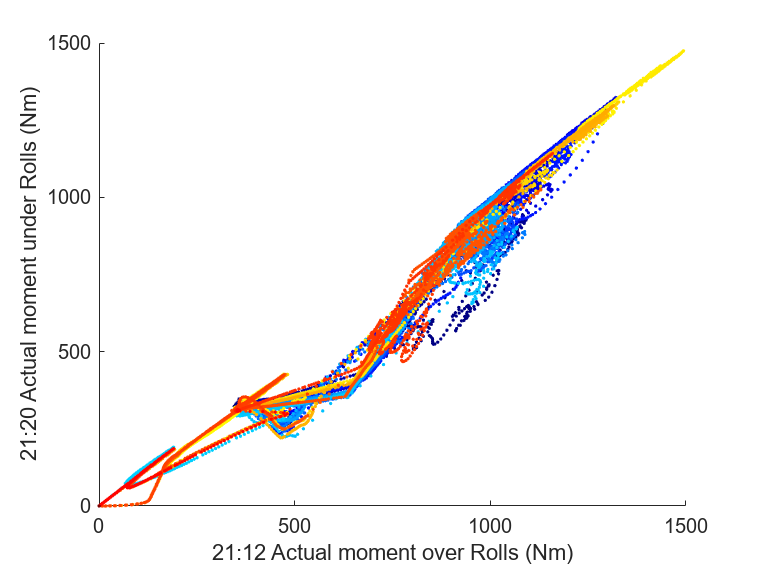

fileNum = 1;
fnPlotCorrelations(rawDataArray, r2Values, fileNum, 0.2, 0.95, sensorNames, sensorNames);

print -depsc '..\Latex Document\figures\RawSignalCorrelationsFile1';

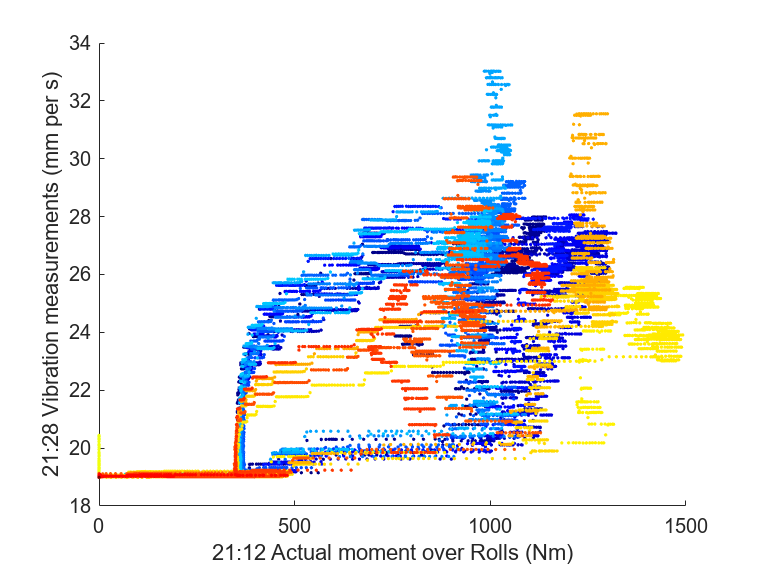

figure();
fileNum = 1;
signalIndex1 = 3;
signalIndex2 = 6;

numpoints = size(cell2mat(rawDataArray{fileNum}(1, 2)), 1);
pointidx = 1 : numpoints; 

sig1 = cell2mat(rawDataArray{fileNum}(signalIndex1, 2));
sig2 = cell2mat(rawDataArray{fileNum}(signalIndex2, 2));
scatter(sig1, sig2, 3, pointidx, 'filled');
colormap( jet(numpoints) );
xlabel(char(sensorNames(signalIndex1)));
ylabel(char(sensorNames(signalIndex2)));
print -depsc '..\Latex Document\figures\Signal21_12vSignal21_28';

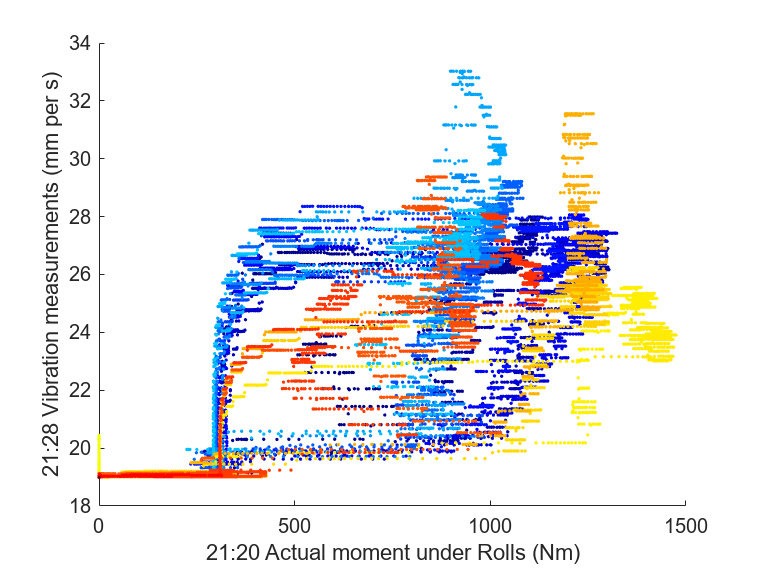

figure();
fileNum = 1;
signalIndex1 = 5;
signalIndex2 = 6;

numpoints = size(cell2mat(rawDataArray{fileNum}(1, 2)), 1);
pointidx = 1 : numpoints; 

sig1 = cell2mat(rawDataArray{fileNum}(signalIndex1, 2));
sig2 = cell2mat(rawDataArray{fileNum}(signalIndex2, 2));
scatter(sig1, sig2, 3, pointidx, 'filled');
colormap( jet(numpoints) );
xlabel(char(sensorNames(signalIndex1)));
ylabel(char(sensorNames(signalIndex2)));
print -depsc '..\Latex Document\figures\Signal21_20vSignal21_28';

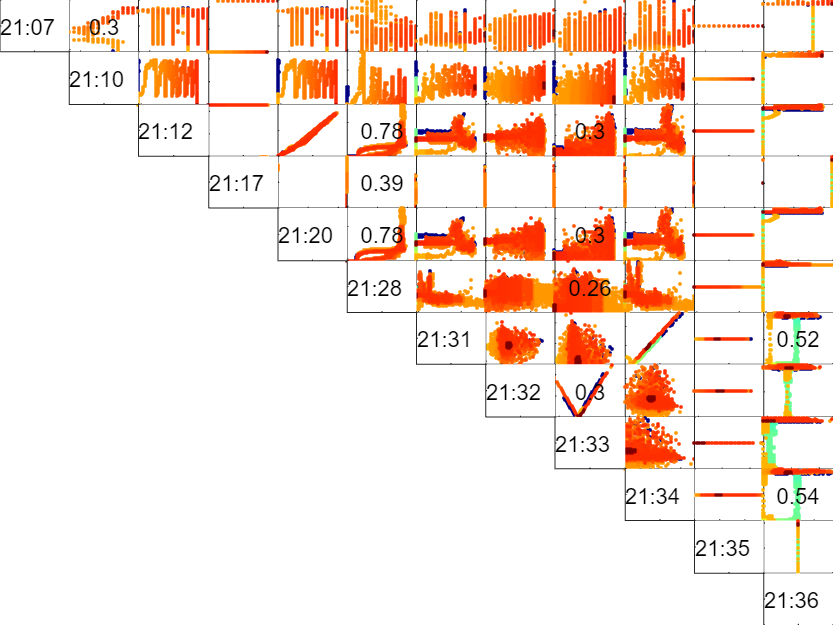

fileNum = 2;
fnPlotCorrelations(rawDataArray, r2Values, fileNum, 0.2, 0.95, sensorNames, sensorNames);

print -depsc '..\Latex Document\figures\RawSignalCorrelationsFile2';

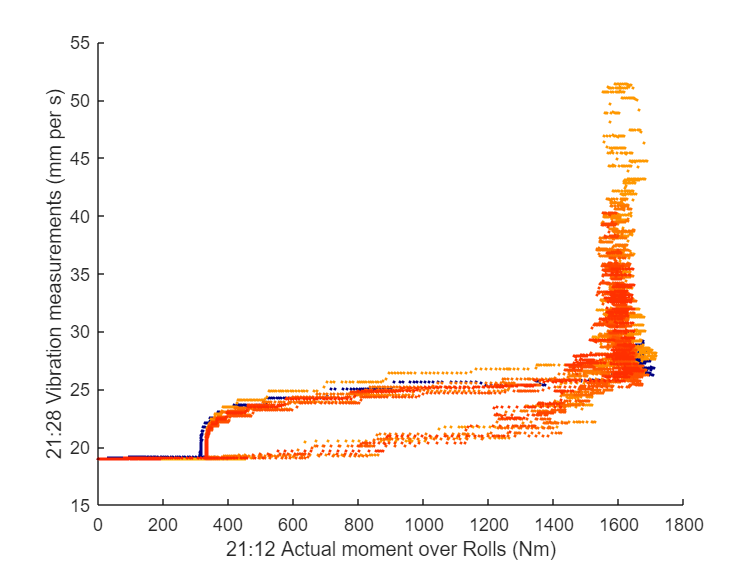

figure();
fileNum = 2;
signalIndex1 = 3;
signalIndex2 = 6;

numpoints = size(cell2mat(rawDataArray{fileNum}(1, 2)), 1);
pointidx = 1 : numpoints; 

sig1 = cell2mat(rawDataArray{fileNum}(signalIndex1, 2));
sig2 = cell2mat(rawDataArray{fileNum}(signalIndex2, 2));
scatter(sig1, sig2, 3, pointidx, 'filled');
colormap( jet(numpoints) );
xlabel(char(sensorNames(signalIndex1)));
ylabel(char(sensorNames(signalIndex2)));

%print -depsc '..\Latex Document\figures\Signal21_12vSignal21_28';

function [] = fnPlotCorrelations(rawDataArray, r2Values, fileNum, lowerBound, upperBound, signalName, sensorNames)
    figure();
    t = tiledlayout(12,12,'TileSpacing','None', 'Padding','tight');
    %title(t, "Raw signals vs each other: File number " + fileNum);
    numOfSignals = size(signalName, 2);
    numpoints = size(cell2mat(rawDataArray{fileNum}(1, 2)), 1);
    pointidx = 1 : numpoints; 
    for signalIndex1 = 1:numOfSignals
        for signalIndex2 = signalIndex1:numOfSignals
            if signalIndex1 ~= signalIndex2
                sig1 = cell2mat(rawDataArray{fileNum}(signalIndex1, 2));
                sig2 = cell2mat(rawDataArray{fileNum}(signalIndex2, 2));
                nexttile((signalIndex1-1) * numOfSignals + signalIndex2);
                scatter(sig1, sig2, 3, pointidx, 'filled');
                colormap( jet(numpoints) );
                xticklabels({});
                yticklabels({});

                DataX = interp1( [0 1], xlim(), 0.5 );
                DataY = interp1( [0 1], ylim(), 0.5 );

                r2Val = r2Values(fileNum, signalIndex1, signalIndex2);
                if r2Val > lowerBound && r2Val < upperBound
                    text(DataX, DataY, num2str(r2Val, 2), 'HorizontalAlignment','center');
                end
            end
        end
    end
    % Add labels for signal names on the diagonals
    for i = 1:size(sensorNames, 2)
        nexttile((i-1) * numOfSignals + i);
        str = char(sensorNames(i));
        text(0, 0.5, str(1:5));
        xticklabels({});
        yticklabels({});
    end
end